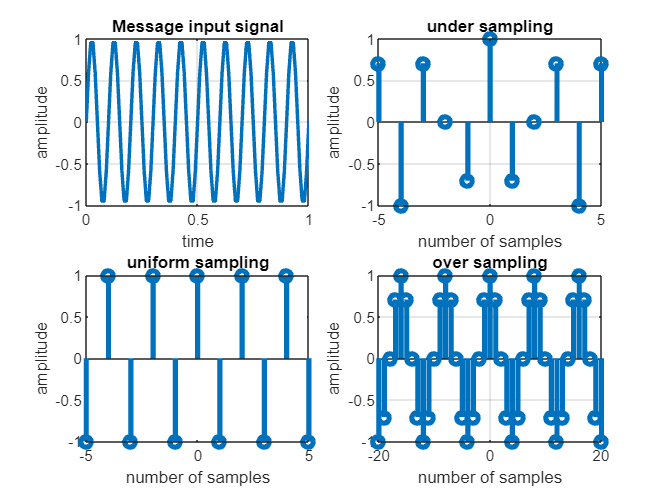

%sampling
close all;
clc;
t = 0:0.01:1; % Time Vector
fm = 10; % Message (Input) signal amplitude
Am = 1; % (Input) signal amplitude
x = Am * sin(2 * pi * fm * t); % Message signal
subplot(2, 2, 1);
plot(t, x, 'linewidth', 2);
xlabel('time');
ylabel('amplitude');
grid;
title('Message input signal');
n1 = -5:1:5;
fs1 = 1.6 * fm;
fs2 = 2 * fm;
fs3 = 8 * fm;

x1 = Am * cos(2 * pi * fm / fs1 * n1);
subplot(2, 2, 2);
stem(n1, x1, 'linewidth', 3);
xlabel('number of samples');
ylabel('amplitude');
grid on;
title('under sampling');
n2 = -5:1:5;
x2 = cos(2 * pi * fm / fs2 * n2);
subplot(2, 2, 3);
stem(n2, x2, 'linewidth', 3);
xlabel('number of samples');
ylabel('amplitude');
hold on;
title('uniform sampling');
n3 = -20:1:20;
x3 = cos(2 * pi * fm / fs3 * n3);
subplot(2, 2, 4);
stem(n3, x3, 'linewidth', 3);
hold on;
xlabel('number of samples');
ylabel('amplitude');
grid;
title('over sampling');